## Task 1

### a)

syms s

num = (s+2-i)*(s+2+i)

$$num = \left(s+2-\mathrm{i}\right)\,\left(s+2+\mathrm{i}\right)$$

denum = s^2 * (s+4)^2

$$denum = s^{2}\,{\left(s+4\right)}^{2}$$


expanded_num = expand(num)

$$expanded\_num = s^{2}+4\,s+5$$

expanded_denum = expand(denum)

$$expanded\_denum = s^{4}+8\,s^{3}+16\,s^{2}$$


G = num/denum

$$G = \frac{\left(s+2-\mathrm{i}\right)\,\left(s+2+\mathrm{i}\right)}{s^{2}\,{\left(s+4\right)}^{2}}$$

s=tf("s");

num = (s+2-i)*(s+2+i)

num =
 
  s^2 + 4 s + 5
 
Continuous-time transfer function.
Model Properties


denum = s^2 * (s+4)^2;

G = num/denum

G =
 
     s^2 + 4 s + 5
  --------------------
  s^4 + 8 s^3 + 16 s^2
 
Continuous-time transfer function.
Model Properties



zeros = zero(G)

zeros =   -2.0000 + 1.0000i
  -2.0000 - 1.0000i


poles = pole(G)

poles =      0
     0
    -4
    -4


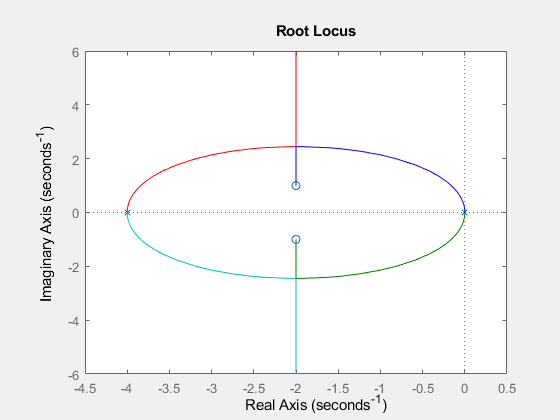


rlocus(G)

### b)

syms s k;
%s = tf("s")

n = s+5;
d = (s + 2) * (s+3);

G=k*n/d

$$G = \frac{k\,\left(s+5\right)}{\left(s+2\right)\,\left(s+3\right)}$$


simplify(diff(-1/G))

$$ans = -\frac{s^{2}+10\,s+19}{k\,{\left(s+5\right)}^{2}}$$

roots(s^2+10*s+19)

 
ans =
 
Empty sym: 0-by-1
 



addpath(".\functions\");

syms s k;
n = s+5;
d = (s + 2) * (s+3);
G=k*n/d

$$G = \frac{k\,\left(s+5\right)}{\left(s+2\right)\,\left(s+3\right)}$$

%solve(diff(-1/G)==0,s)
break_points(G,s)

$$ans = \left(\begin{array}{c} -\sqrt{6}-5\\ \sqrt{6}-5 \end{array}\right)$$



p1 =-sqrt(6)-5

p1 = -7.4495

p2 = sqrt(6)-5

p2 = -2.5505

### C)

s = tf("s");

n = s+5;
d = (s + 2) * (s+3);

G=n/d

G =
 
      s + 5
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties



p = pole(G);
z = zero(G);

m = length(p);

n = length(z);

a = m-n;
abs_a = abs(a);

q = 0:1:abs_a-1;

half_circle = 180;

asymptote_array = half_circle*(2*q+1)/abs_a

asymptote_array = 180

centroid = (sum(p) - sum(z))/a

centroid = 0

### D)

s = tf("s");

n = s+5;
d = (s + 2) * (s+3);

G=n/d

G =
 
      s + 5
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties



rlocus(G)         % Root locus


wanted_Zeta = 0.9

wanted_Zeta = 0.9000

sgrid(wanted_Zeta,0)


% repeat this line with a new k for every time the sgrid line, crosses the
% root locus.
k1 = rlocfind(G) 

Select a point in the graphics window


selected_point = -3.0972 - 1.5046i

k1 = 1.1574

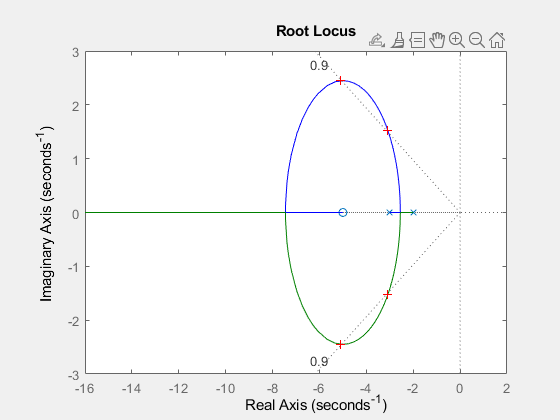

Select a point in the graphics window


selected_point = -5.1019 - 2.4334i

k2 = 5.2050

k2 = rlocfind(G)


% rlocfind wants you to click on the rootlocus to find the gain value that
% achieves the point you clicked on. since the sgrid line shows the
% poisition to click for all gains that result in the wanted dampening
% ratio (wanted zeta value)

## Task 2

### a)

%% Task 2
syms h h0

v = @(h) -0.02*h^2 + 0.94*h - 0.84

v = function_handle with value:
    @(h)-0.02*h^2+0.94*h-0.84



v_linear = v(h0) + diff(v(h0))*(h-h0)

$$v\_linear = \frac{47\,h_{0}}{50}-\left(\frac{h_{0}}{25}-\frac{47}{50}\right)\,\left(h-h_{0}\right)-\frac{{h_{0}}^{2}}{50}-\frac{21}{25}$$


subs(v_linear, h0, 12)

$$ans = \frac{23\,h}{50}+\frac{51}{25}$$


vh0 = v(h0)

$$vh0 = -\frac{{h_{0}}^{2}}{50}+\frac{47\,h_{0}}{50}-\frac{21}{25}$$

svh0 = subs(vh0,h0,18)

$$svh0 = \frac{48}{5}$$

fprintf("%f",svh0)

9.600000

$$svh0 = \frac{48}{5}$$

syms x(t) x0

f = @(x) diff(x,t,2) + 2*diff(x,t) + cos(x) == 0

f = function_handle with value:
    @(x)diff(x,t,2)+2*diff(x,t)+cos(x)==0



f_linear = f(x0) + diff(f(x0))*(x-x0)

$$f\_linear(t) = \cos\left(x_{0}\right)+\sin\left(x_{0}\right)\,\left(x_{0}-x\left(t\right)\right)=0$$


lf = subs(f_linear,x0,pi/4)

$$lf(t) = \frac{\sqrt{2}\,\left(\frac{\pi }{4}-x\left(t\right)\right)}{2}+\frac{\sqrt{2}}{2}=0$$

syms s
%s = tf("s");

n = 10;
d = s*(s + 5);

G=n/d

$$G = \frac{10}{s\,\left(s+5\right)}$$

%nyquist(G)
partfrac(G,s)

$$ans = \frac{2}{s}-\frac{2}{s+5}$$

syms s z n T
%s = tf("s");

nu = 1 - exp(-s*T);
de = 1;
%nu = 10;
%de =  s * (s+5);

G=nu/de

$$G = 1-{\mathrm{e}}^{-T\,s}$$


ztrans(ilaplace(G))

$$ans = \mathrm{ztrans}\left(\delta (t),t,z\right)-\mathrm{ztrans}\left(\mathrm{ilaplace}\left({\mathrm{e}}^{-T\,s},s,t\right),t,z\right)$$

syms x n 
v = 1;
sympref('HeavisideAtOrigin', v);
x = heaviside(n-1);
H = ztrans(x)

[num, den] = numden(H);
H = tf(sym2poly(num), sym2poly(den), -1)